**Przydatne funkcje:**

`inv() `- Operator do wyznaczenia macierzy odwrotnej.

`diag()` - Konstruuje macierz diagonalną.

`tf()` - Konstruuje transmitancję.

`lsim()` - Symuluje odpowiedź czasową systemów dynamicznych na dowolne dane wejściowe.

`mean(`) - Wyznaczenie średniej.

`mse()` - Wyznaczenie błędu średnio-kwadratowego.

`var()` - Wyznaczenie błędu średnio-kwadratowego.

Więcej informacji można uzyskać używając komendy `help ``nazwa_funkcji` w ***Command Window***

**Przydatne może okazać się również** [indeksowanie logiczne](https://www.mathworks.com/help/matlab/math/array-indexing.html#MatrixIndexingExample-3).

Kod wykonywany w [Live Script](https://www.mathworks.com/help/matlab/live-scripts-and-functions.html) może być dzielony na sekcje (mniejsze fragmenty kodu), umożliwiając przy tym wykonanie kodu pojedyńczej sekcji lub wielu sekcji z poziomu paska nawigacji `SECTION`.

clc; clear; clearvars; close all;

load MiI_P1_grupa_1a.mat;

y1 = y_cz1.signals.values;
y2 = y_cz2.signals.values;
u_we = u.signals.values;
krok_td = td;

N_all = length(y1);
N_estymacji = floor(N_all/1); 
N_estymacji1 = 3001-floor(N_all/2);
t_all = (0:N_all-1)' * krok_td;

fprintf('Czujnik 1\n');

Czujnik 1



% Zakres czujnik 1
y1_min = 2.0; 
y1_max = 5.0;  

% Wagi
wagi_do_testu = [1, 10, 100]; 

figure('Name', 'Porównanie modeli - Czujnik 1', 'NumberTitle', 'off');
hold on;
plot(t_all, y1, 'k', 'LineWidth', 1.5, 'DisplayName', 'Dane rzeczywiste');

for i = 1:length(wagi_do_testu)
    waga = wagi_do_testu(i);
    fprintf('\nWAGA= %d\n', waga);
    
    [theta_cz1, sys_cz1] = analizuj_czujnik(y1, u_we, krok_td,N_estymacji1, N_estymacji, y1_min, y1_max, waga);
    
    disp('Wyestymowane parametry dyskretne theta:'); disp(theta_cz1');
    disp('Transmitancja obiektu G(s):'); sys_cz1
    
    y_symulowane1 = lsim(sys_cz1, u_we, t_all);
    plot(t_all, y_symulowane1, '--', 'LineWidth', 1.2, 'DisplayName', ['Model (Waga=', num2str(waga), ')']);
end


WAGA= 1


 -> W zbiorze estymacyjnym (1500 próbek) znaleziono 449 DOKŁADNYCH danych.
   Zgodność REPLIKATYWNA  Średnia: 0.0280298 | MSE: 0.0822308 | Wariancja: 0.0814995
   Zgodność PREDYKATYWNA  Średnia: 0.00143393 | MSE: 0.0195771 | Wariancja: 0.0195816


Wyestymowane parametry dyskretne theta:
    0.8696    0.0521



Transmitancja obiektu G(s):

sys_cz1 =
 
    5.985
  ---------
  s + 14.99
 
Continuous-time transfer function.
Model Properties



WAGA= 10


 -> W zbiorze estymacyjnym (1500 próbek) znaleziono 449 DOKŁADNYCH danych.
   Zgodność REPLIKATYWNA  Średnia: 0.0845405 | MSE: 0.0876166 | Wariancja: 0.0805232
   Zgodność PREDYKATYWNA  Średnia: 0.0430823 | MSE: 0.0171621 | Wariancja: 0.0153111


Wyestymowane parametry dyskretne theta:
    0.8848    0.0456



Transmitancja obiektu G(s):

sys_cz1 =
 
    5.152
  ---------
  s + 13.02
 
Continuous-time transfer function.
Model Properties



WAGA= 100


 -> W zbiorze estymacyjnym (1500 próbek) znaleziono 449 DOKŁADNYCH danych.
   Zgodność REPLIKATYWNA  Średnia: 0.122845 | MSE: 0.0954678 | Wariancja: 0.0804304
   Zgodność PREDYKATYWNA  Średnia: 0.0715083 | MSE: 0.0192647 | Wariancja: 0.014156


Wyestymowane parametry dyskretne theta:
    0.8916    0.0426



Transmitancja obiektu G(s):

sys_cz1 =
 
    4.78
  ---------
  s + 12.15
 
Continuous-time transfer function.
Model Properties


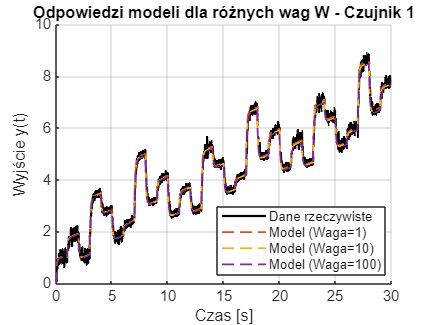


legend('show', 'Location', 'best');
title('Odpowiedzi modeli dla różnych wag W - Czujnik 1');
xlabel('Czas [s]'); ylabel('Wyjście y(t)'); grid on; hold off;


fprintf('Czujnik 2\n');

Czujnik 2



% Zakres czujnik 2
y2_min = 3.0; 
y2_max = 4.0;

figure('Name', 'Porównanie modeli - Czujnik 2', 'NumberTitle', 'off');
hold on;
plot(t_all, y2, 'k', 'LineWidth', 1.5, 'DisplayName', 'Dane rzeczywiste');

for i = 1:length(wagi_do_testu)
    waga = wagi_do_testu(i);
    fprintf('\nWAGA= %d\n', waga);
    
    [theta_cz2, sys_cz2] = analizuj_czujnik(y2, u_we, krok_td,N_estymacji1, N_estymacji, y2_min, y2_max, waga);
    
    disp('Wyestymowane parametry dyskretne theta:'); disp(theta_cz2');
    disp('Transmitancja obiektu G(s):'); sys_cz2
    
    y_symulowane2 = lsim(sys_cz2, u_we, t_all);
    plot(t_all, y_symulowane2, '--', 'LineWidth', 1.2, 'DisplayName', ['Model (Waga=', num2str(waga), ')']);
end


WAGA= 1


 -> W zbiorze estymacyjnym (1500 próbek) znaleziono 119 DOKŁADNYCH danych.
   Zgodność REPLIKATYWNA  Średnia: 0.0295279 | MSE: 0.0809033 | Wariancja: 0.0800848
   Zgodność PREDYKATYWNA  Średnia: 0.000999904 | MSE: 0.011175 | Wariancja: 0.0111777


Wyestymowane parametry dyskretne theta:
    0.8892    0.0443



Transmitancja obiektu G(s):

sys_cz2 =
 
    4.977
  ---------
  s + 12.46
 
Continuous-time transfer function.
Model Properties



WAGA= 10


 -> W zbiorze estymacyjnym (1500 próbek) znaleziono 119 DOKŁADNYCH danych.
   Zgodność REPLIKATYWNA  Średnia: 0.0618564 | MSE: 0.0823943 | Wariancja: 0.0786205
   Zgodność PREDYKATYWNA  Średnia: 0.0256973 | MSE: 0.0121194 | Wariancja: 0.0114629


Wyestymowane parametry dyskretne theta:
    0.8884    0.0444



Transmitancja obiektu G(s):

sys_cz2 =
 
    4.993
  ---------
  s + 12.57
 
Continuous-time transfer function.
Model Properties



WAGA= 100


 -> W zbiorze estymacyjnym (1500 próbek) znaleziono 119 DOKŁADNYCH danych.
   Zgodność REPLIKATYWNA  Średnia: 0.140464 | MSE: 0.0953385 | Wariancja: 0.0756587
   Zgodność PREDYKATYWNA  Średnia: 0.0857023 | MSE: 0.0203439 | Wariancja: 0.0130033


Wyestymowane parametry dyskretne theta:
    0.8866    0.0444



Transmitancja obiektu G(s):

sys_cz2 =
 
    5.011
  ---------
  s + 12.79
 
Continuous-time transfer function.
Model Properties


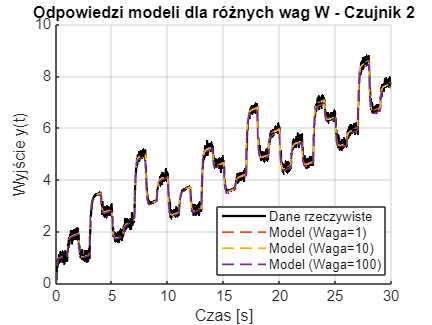


legend('show', 'Location', 'best');
title('Odpowiedzi modeli dla różnych wag W - Czujnik 2');
xlabel('Czas [s]'); ylabel('Wyjście y(t)'); grid on; hold off;

**Funkcje**

Powtarzalny kod warto zaimplementować w [funkcji](https://www.mathworks.com/help/matlab/ref/function.html). 

Przykładowo:

function [theta, sys_c] = analizuj_czujnik(y_wektor, u_wektor, td,N_est1, N_est, y_min, y_max, waga_dokladna)

    y_est = y_wektor(N_est1:N_est);
    u_est = u_wektor(N_est1:N_est);
    
    Y = y_est(2:end);
    Phi = [y_est(1:end-1), u_est(2:end)];
    
    wagi = ones(length(Y), 1); 
    indeksy_dokladne = (Y >= y_min) & (Y <= y_max);
    
    ilosc_dokladnych = sum(indeksy_dokladne);
    fprintf(' -> W zbiorze estymacyjnym (%d próbek) znaleziono %d DOKŁADNYCH danych.\n', length(Y), ilosc_dokladnych);
    
    wagi(indeksy_dokladne) = waga_dokladna;
    W = diag(wagi); 
    
    theta = MWNK(Phi, Y, W);
    
    ao = (1 - theta(1)) / (theta(1) * td);
    bo = theta(2) / (theta(1) * td);
    sys_c = tf(bo, [1, ao]); 
    
    t_all = (0:length(y_wektor)-1)' * td;
    t_est = t_all(N_est1:N_est);
    
    % Zgodność replikatywna
    y_sym_est = lsim(sys_c, u_est, t_est);
    e_rep = y_est - y_sym_est;
    fprintf('   Zgodność REPLIKATYWNA  Średnia: %g | MSE: %g | Wariancja: %g\n', mean(e_rep), mse(e_rep), var(e_rep));
    
    % Zgodność predykatywna
    y_sym_all = lsim(sys_c, u_wektor, t_all);
    e_pred = y_wektor - y_sym_all;
    fprintf('   Zgodność PREDYKATYWNA  Średnia: %g | MSE: %g | Wariancja: %g\n', mean(e_pred), mse(e_pred), var(e_pred));
end

function theta = MWNK(Phi, Y, W)
    % Estymaty parametrów modelu MWNK
    theta = (Phi' * W * Phi) \ (Phi' * W * Y);
end
